# Weights and Balances

clear all; close all; clc;

## Initialization

#### Design Variables

Aerodynamics

%Main Wing
    S = 0.2413;
    b = 1.042;
    c = 0.2316;
    S_wet = 0.502191;

Payload

rho_P2 = 689; %package 2 cardboard density [kg/m^3]
V_P2 = 0.001; %package 2 cardboard volume [m^3]

Fuselage Volumes

%Bulkheads
V_Front = (2142.12/1000^3); %front bulkhead [m^3]
V_NB = (13458.81/1000^3); %nose base bulhead [m^3]
V_BB = (9211.08/1000^3); %battery base bulhead [m^3]
V_RF = (12117.98/1000^3); %receiver face bulhead [m^3]
V_GPS = (11318.36/1000^3); %GPS base bulhead [m^3]
V_CC = (4660.72/1000^3); %cargo chute base bulhead [m^3]

%Carbon Fiber Rods
V_CFR = (37613.88/1000^3); %carbon fiber rods [m^3]

%3D Printed Rod // Stabilizer // Landing Gear Mount
V_F3D = (66016/1000^3); %carbon fiber rods [m^3]

Densities

d_balsa = 160; %balsa wood density [kg/m^3]
d_CF = 1500; %carbon fiber density [kg/m^3]
d_PLA = 1250; %PLA density [kg/m^3]

#### Target Stability

SM_target = 10; %Static Margin Target

## Loop Initialization

Initial Guesses

AL = 2; %aircraft length [m]
L_MW = 300/1000; %location of leading edge of main wing from front
L_TW = 0.8; %location of leading edge of tail wings from front
LT = 1; %distance from MW 1/4 chord to tail 1/4 chord
L_F = 0.1; %distance from front to start of fuselage

## Tail Sizing

#### Specified Values

CHT = 0.55; %horizontal tail volume coefficient
AR_HT = 4.5; %horizontal tail aspect ratio
CVT = 0.04; %vertical tail volume coefficient
AR_VT = 1.5; %vertical tail aspect ratio

#### Calculations

S_HT = (CHT*c*S)/LT

S_HT = 0.0307

    b_HT = sqrt(AR_HT*S_HT) %wing span

b_HT = 0.3719

    c_HT = b_HT/AR_HT %chord length

c_HT = 0.0826

S_VT = (CVT*c*S)/LT

S_VT = 0.0022

    b_VT = sqrt(AR_VT*S_VT) %wing span

b_VT = 0.0579

    c_VT = b_VT/AR_VT %chord length

c_VT = 0.0386

## Center of Gravity

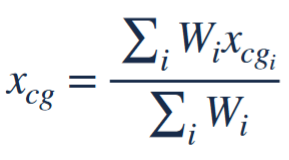

#### Wing CG

    Wing Weight:

%Main Wing
        V_rib = 6303.1098/1000^3; %rib volume [m^3]
        n_rib = 19;
        V_MW_CF = pi*(8/1000)^2*b + (2/1000)*(6/1000)*2*b; %carbon fiber volume
    m_MW = V_rib*n_rib*d_balsa + V_MW_CF*d_CF; %main wing mass [kg]
    d_wing = m_MW/S; %approximate mass per wing area
m_HT = S_HT*d_wing*0.9; %horizontal tail mass [kg]
m_VT = S_VT*d_wing*0.9; %vertical tail mass [kg]

    Local CG

CG_L_MW = 0.25; %local center of gravity (main wing)
CG_L_HT = 0.25; %local center of gravity (horizontal tail)
CG_L_VT = 0.25; %local center of gravity (vertical tail)

    Global CG

CG_G_MW = L_MW + CG_L_MW*c; %global main wing CG
CG_G_HT = CG_G_MW + LT;
CG_G_VT = CG_G_MW + LT;

#### Fuselage CG

    Fuselage Weight

%Nose (PLA)
m_Nose = 3*V_NB*d_PLA;

%Bulkheads (Balsa)
m_Front = V_Front*d_balsa; %front bulkhead mass [kg]
m_NB = V_NB*d_balsa; %nose base bulkhead mass [kg]
m_BB = V_BB*d_balsa; %battery base bulkhead mass [kg]
m_RF = V_RF*d_balsa; %receiver face bulkhead mass [kg]
m_GPS = V_GPS*d_balsa; %GPS base bulkhead mass [kg]
m_CC = V_CC*d_balsa; %cargo chute bulkhead mass [kg]

%Carbon Fiber Rods
m_CFR = V_CFR*d_CF; %carbon fiber rods mass [kg]

%3D Printed Rod // Stabilizer // Landing Gear Mount
m_F3D = V_F3D*d_PLA; %3D printed material mass [kg]

    Global:

%Nose
CG_Nose = -25/1000; %nose CG [mm] from front

%Bulkheads
CG_Front = 1/1000; %front bulkhead CG [mm] from front
CG_NB = 98.7/1000; %nose base bulkhead CG [mm] from front
CG_BB = 254/1000; %battery base bulkhead CG [mm] from front
CG_RF = 375.75/1000; %receiver face bulkhead CG [mm] from front
CG_GPS = 489.95/1000; %GPS base bulkhead CG [mm] from front
CG_CC = 650/1000; %cargo chute bulkhead CG [mm] from front

%Carbon Fiber Rods
CG_CFR = 619.75/1000; %carbon fiber rods CG [mm] from front

%3D Printed Rod // Stabilizer // Landing Gear Mount
CG_F3D = 923/1000; %3D printed material CG [mm] from front

#### Components

    Component Weights

m_Motor = 0.0730; %motor mass [kg]
m_SC = 0.051; %speed controller mass [kg]
m_Bat = 0.156; %battery mass [kg]
m_Rec = 0.0166; %receiver mass [kg]
m_LG = 0.032; %landing gear mass [kg]
    m_FLG = 25.6/1000; %front landing gear mass [kg] CHANGE
    m_RLG = 6.4/1000; %front landing gear mass [kg] CHANGE
m_WM = 0.082; %watt meter mass [kg]
m_Prop = 0.001; %propeller mass [kg]
m_P1 = 0.7921; %package 1 mass [kg]
m_P2 = rho_P2*V_P2; %package 2 mass [kg]

    Component Locations

CG_G_Motor = 0/1000; %motor
CG_G_SC = 59.7/1000; %speed controller
CG_G_Bat = 100/1000; %battery
CG_G_Rec = 400/1000; %receiver
CG_G_FLG = 153.05/1000; %front landing gear
CG_G_RLG = 1054.91/1000; %rear landing gear
CG_G_WM = 125/1000; %watt meter
CG_G_Prop = 0/1000; %propeller
%CG_G_P1 = 59.7/1000; %package 1
CG_G_P2 = 600/1000; %package 2

#### Other

All-else Empty

m_AEE = 2; %all else empty mass [kg]
CG_G_AEE = 2; %all else empty CG

### CG Location

%Wing CG
    m_W = m_MW + m_HT + m_VT; %overall wing mass
    CG_W = (CG_G_MW*m_MW + CG_G_HT*m_HT + CG_G_VT*m_VT)/(m_MW + m_HT + m_VT); %overall CG of wings
%Fuselage CG
    m_F = m_Nose + m_Front + m_NB + m_BB + m_RF + m_GPS + m_CC + m_CFR + m_F3D;
    CG_F = (m_Nose*CG_Nose + m_Front*CG_Front+m_NB*CG_NB+m_BB*CG_BB+m_RF*CG_RF+m_GPS*CG_GPS+m_CC*CG_CC+m_CFR*CG_CFR+m_F3D*CG_F3D)/m_F;
%Component CG
    m_C = m_Motor+m_SC+m_Bat+m_Rec+m_FLG+m_RLG+m_WM+m_Prop+m_P2; %overall component mass
    CG_C = (CG_G_Motor*m_Motor+CG_G_SC*m_SC+CG_G_Bat*m_Bat+CG_G_Rec*m_Rec+CG_G_FLG*m_FLG+CG_G_RLG*m_RLG+CG_G_WM*m_WM+CG_G_Prop*m_Prop+CG_G_P2*m_P2)/(m_C); %overall component CG 

%Overall CG
    CG_Overall = (CG_W*m_W + CG_F*m_F + CG_C*m_C)/(m_W + m_F + m_C);
    %CG_Overall = (CG_W*m_W + CG_F*m_F + CG_C*m_C + CG_G_AEE*m_AEE)/(m_W
    %+ m_F + m_C + m_AEE); [USE IF AEE IS APPLICABLE]


Report as a percent of MAC

CG = (CG_Overall-L_MW)/c

CG = 0.6353

## Aerodynamic Center

#### Local Aerodynamic Center

AC_L_MW = 0.25; %local aerodynamic center (main wing)
AC_L_HT = 0.25; %local aerodynamic center (horizontal tail)
AC_L_VT = 0.25; %local aerodynamic center (vertical tail)

#### Global Aerodynamic Center

AC_G_MW = CG_G_MW; %global aerodynamic center (main wing)
AC_G_HT = CG_G_HT; %global aerodynamic center (horizontal tail)
AC_G_VT = CG_G_VT; %global aerodynamic center (vertical tail)

## Neutral Point

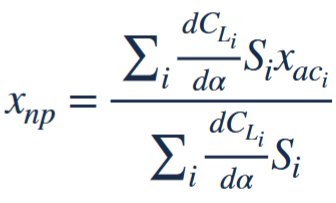

#### Lift Curve Slopes

LCS_MW = 0.1506; %main wing lift curve slope
LCS_HT = 0.12; %horizontal tail lift curve slope [CHANGE]
LCS_VT = 0.12; %vertical tail lift curve slope [CHANGE]

#### Neutral Point

NP_Overall = (LCS_MW*S*AC_G_MW + LCS_HT*S_HT*AC_G_HT + LCS_VT*S_VT*AC_G_VT)/(LCS_MW*S + LCS_HT*S_HT + LCS_VT*S_VT); %neutral point

Report as a percent of MAC

NP = (NP_Overall-L_MW)/c

NP = 0.6740

## Stability Analysis

SM = (NP_Overall - CG_Overall)/c %static margin

SM = 0.0386

## Plot

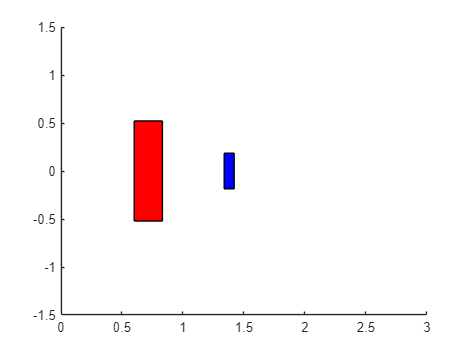

figure()
hold on
rectangle('Position',[L_MW*AL, -b/2, c, b],'FaceColor','r')
rectangle('Position',[CG_G_HT-(c_HT/4), -b_HT/2, c_HT, b_HT],'FaceColor','b')
xlim([0,3])
ylim([-1.5, 1.5])